# Beyond Raman Nath Regime

## Initialization



units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
add_Li = aLi_12*0.6;

totalODTpower = 22.5;
EndODTpower = 22.5;

omegax = 81*pi*2*sqrt(EndODTpower/totalODTpower); % trap frequencies 
omegay = 3040*pi*2*sqrt(EndODTpower/totalODTpower);
omegaz = 3040*pi*2*sqrt(EndODTpower/totalODTpower);

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;

D = Wavelength/2; % Lattice period 0.532 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 

LatticePotential = 50; % lattice depth in unit of recoil energy
V = @(X,Y,Z) 0.5*(X.^2 + (omegay/omegax* Y).^2); % function representing the external potential (must have 3 arguments)


ymax = 25*D/rscale; %  grid boundaries [-xmax,xmax]
xmax = 800*D/rscale; %  grid boundaries [-xmax,xmax]
Nx = 32000; % number of grid points for coordinate grid
Ny = 1000;


useGPU = true;

if gpuDeviceCount>0 && useGPU
    x = gpuArray.linspace(-xmax,xmax,Nx);
    y = gpuArray.linspace(-ymax,ymax,Ny);
    grid = grid2d(x,y);
    a = gpuDevice;
    fprintf('GPU is burning now! %4.2f %% has been used',a.AvailableMemory/a.TotalMemory*100)
else
    grid = grid2d(xmax,Nx,ymax,Ny); % create a two-dimensional NxN grid object
end

GPU is burning now! 55.33 % has been used


task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)


task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;


## Stationary state calculation

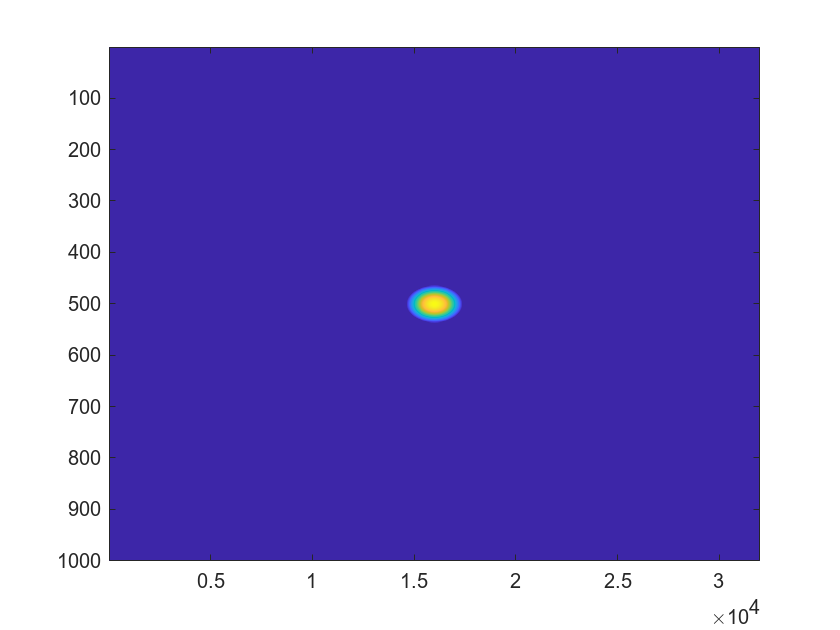


% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);

% Plot the initial state
imagesc(abs(phi).^2)


task.g = 4*pi*add_Li/rscale/sqrt(2*pi/sqrt(omegaz*omegay)*omegax); % nonlinear interaction constant


%% switch on lattice for Deltat
Deltat = 1*10^-6/tscale; % total duration for simulation; (20 mico-seconds)
tstep = 2*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

task.init_state = phi;
task.show_image = 0; % show the solution on every precessing step
task.whisper = 0;    % print our the details about each iteration



Px = [-1 0 1]; %  Modes of momentum to be analyzed
Py = [-1 0 1];


% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)...
    *(  cos((pi/D)*X*rscale).^2 +...
        cos((pi/D)*Y*rscale).^2 +...
        2*cos((pi/D)*X*rscale).*cos((pi/D)*Y*rscale)   ); 
task.UpdatePotential(Vlattice);
% task.history.MomentumDensity = [];
task.user_callback = @(x)task.FFTanalysis2Darb(true,Px,Py);
steps_ext = task.current_iter + Deltat/tstep/steps_int;


## start simulation

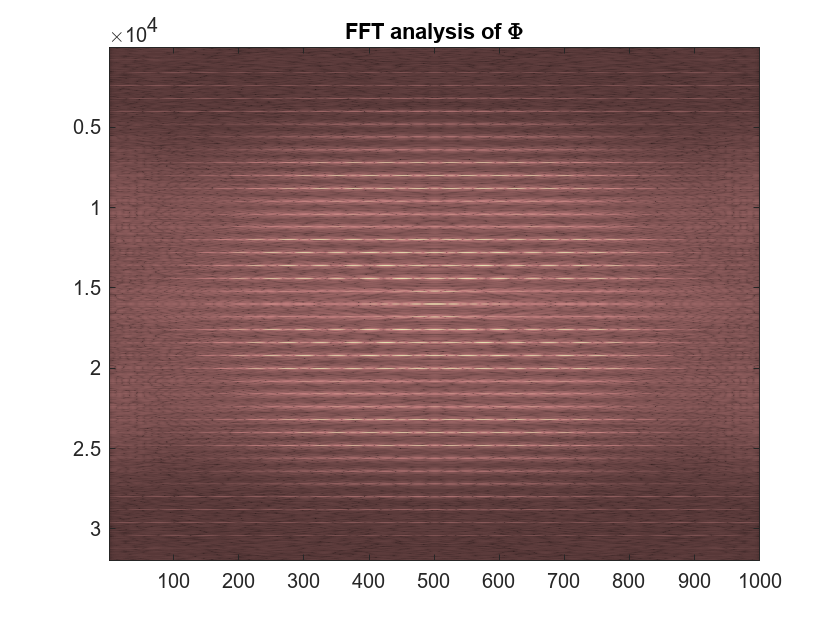


task.solve_split(tstep,steps_int,steps_ext); % run the calculation

## momentum modes distribution

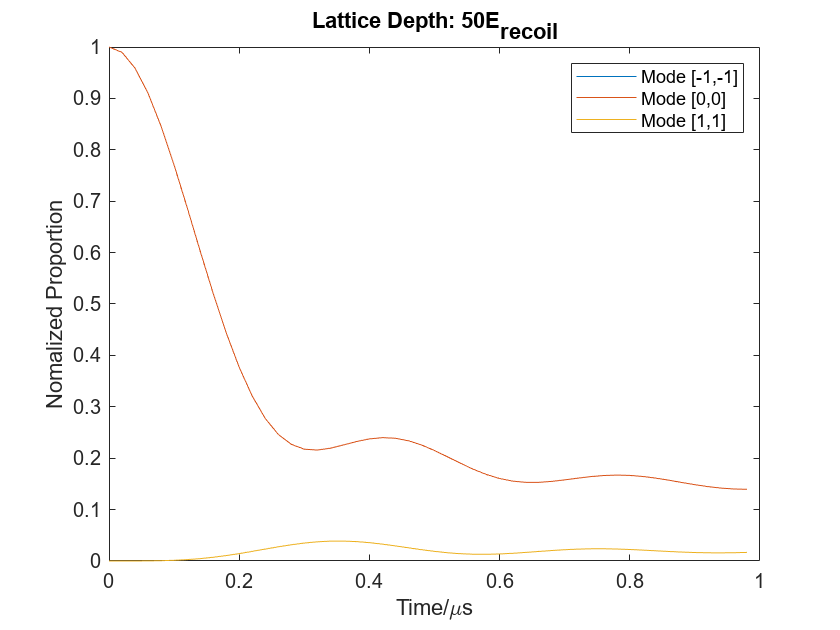


trange = (0:steps_ext)*tstep*steps_int*tscale;
MomentumDensity = Get_momentumDesity_2D( ...
    task.history.MomentumDensity,1:length(Px),1);
MomentumDensity = MomentumDensity./max(MomentumDensity(:));

for i = 1:length(Px)
    
plot(trange*10^6, MomentumDensity(:,i), ...
    'DisplayName',['Mode [' ,num2str(Px(i)), ',',num2str(Py(i)) ,']'])
hold on
end
hold off
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend

##  Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 0.6509

% task.whisper = 0;
% options = optimoptions(@fminunc,'Display','iter','PlotFcn','optimplotfval' ,'StepTolerance',0.01);
% problem.options = options;
% % problem.x0 = rand(1,3);
% problem.x0 = [0.1 0.5 0.4];
% % problem.x0 = 4;
% problem.objective = @(x) PulseSequenceEvolve(task,x);
% problem.solver = 'fminunc';
% task.userData.LatticeP = Vlattice;
% x = fminunc(problem)

function SecondOrderMomentum = PulseSequenceEvolve(task,PulseSequenceNum)
PulseSequence = PulseSequenceNum*10^-6/task.Tscale; % duration for simulation

steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)
tstep = sum(PulseSequence)/steps_int/10; % time step for calculation;
task.show_image = 0; % show the solution on every precessing step

task.reInitialize
NmaxP = 2; % maximum mode of momentum to be analyzed
task.FFTanalysis2D(false,NmaxP);
MomentumDensityInitial = task.history.MomentumDensity{1};
task.user_callback = @(x)0;
PotentialOn = -1;
for Deltat = PulseSequence

    PotentialOn = -PotentialOn;
    if PotentialOn > 0
        % function representing the external potential (must have 3 arguments)
        Vpotential = task.userData.LatticeP; 
    else
        Vpotential = @(X,Y,Z) 0; 
    end

    task.UpdatePotential(Vpotential);
    steps_ext = task.current_iter + round( Deltat/tstep/steps_int);
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation
end

task.FFTanalysis2D(false,NmaxP);
MomentumDensity = task.history.MomentumDensity{end};
MomentumDensity = MomentumDensity./max(MomentumDensityInitial(:));
SecondOrderMomentum = -MomentumDensity(NmaxP+1,NmaxP);
end